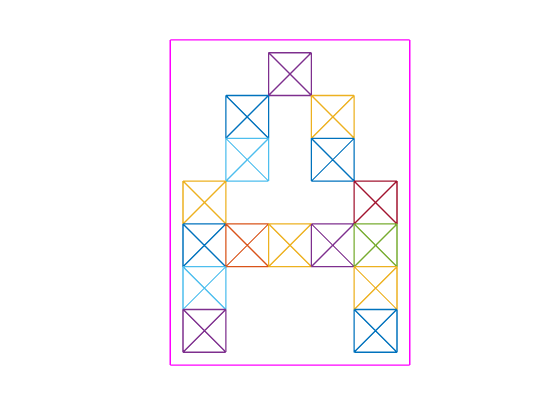

[X,T] = prprob;
plotchar(X(:,1))

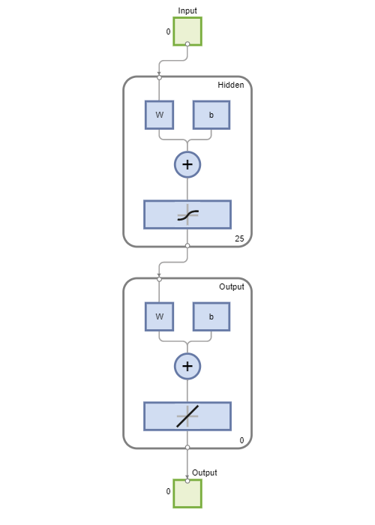


setdemorandstream(pi);
net1 = feedforwardnet(25);
view(net1)


net1.divideFcn = '';
net1 = train(net1,X,T,nnMATLAB);

 
Computing Resources:
MATLAB on PCWIN64
 


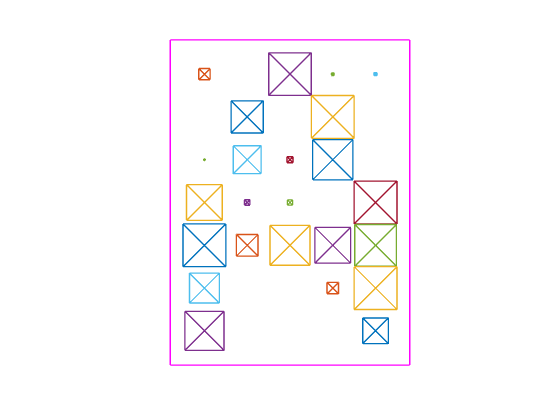


numNoise = 30;
Xn = min(max(repmat(X,1,numNoise)+randn(35,26*numNoise)*0.2,0),1);
Tn = repmat(T,1,numNoise);

figure
plotchar(Xn(:,1))

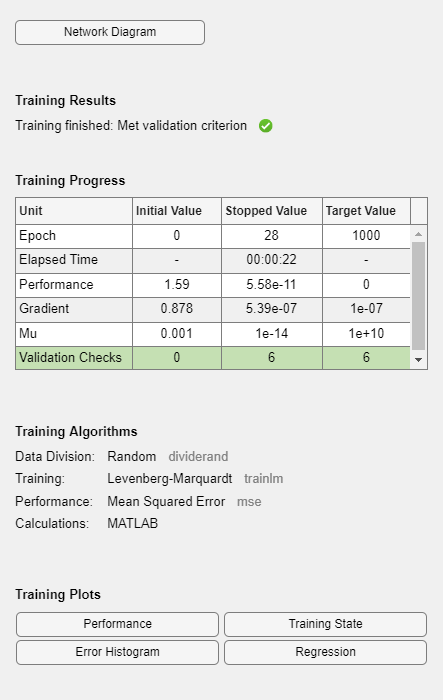

 
Computing Resources:
MATLAB on PCWIN64
 



net2 = feedforwardnet(25);
net2 = train(net2,Xn,Tn,nnMATLAB);

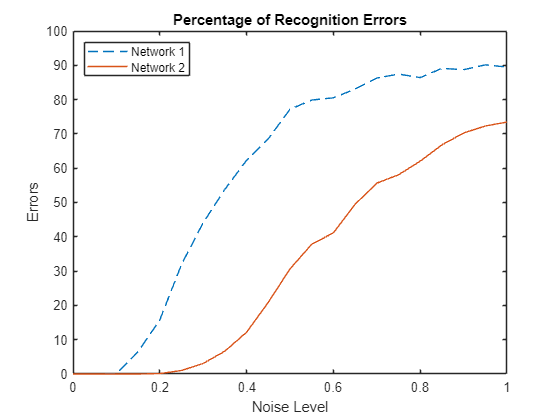


noiseLevels = 0:.05:1;
numLevels = length(noiseLevels);
percError1 = zeros(1,numLevels);
percError2 = zeros(1,numLevels);
for i = 1:numLevels
  Xtest = min(max(repmat(X,1,numNoise)+randn(35,26*numNoise)*noiseLevels(i),0),1);
  Y1 = net1(Xtest);
  percError1(i) = sum(sum(abs(Tn-compet(Y1))))/(26*numNoise*2);
  Y2 = net2(Xtest);
  percError2(i) = sum(sum(abs(Tn-compet(Y2))))/(26*numNoise*2);
end

figure
plot(noiseLevels,percError1*100,'--',noiseLevels,percError2*100);
title('Percentage of Recognition Errors');
xlabel('Noise Level');
ylabel('Errors');
legend('Network 1','Network 2','Location','NorthWest')